# Experimental Design Matrix for Frontier Methods with Preprocessing

## *Chocó Map*

### 0. Preparing environment

#### 1. Clear command window, workspace variables, and close all figures. Turn off warnings.

clear; clc; close all;
warning('off', 'all');

#### 2. Set the path to the folder containing the layer data

layerfolder = 'data/layers/';

#### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 2.400508 seconds.


Defining Experimental Matrix

mapsAmount = 20;
nicheOccupations = [0.3, 0.6, 0.9];
samples = [20, 50, 100, 500];
correlationPercentages = [0.7, 0.8, 0.9];

warning("off", "all")
[matrixPreprocessing, matrixNoPreprocessing] = ExperimentalMatrixCode(Layers, mapsAmount,nicheOccupations,samples,correlationPercentages)

matrixPreprocessing = matrixPreprocessing(:,:,1,1,1) =

    0.8283    0.8650    0.8343
    0.8617    0.8269    0.7015
    0.6856    0.7733    0.8820
    0.7527    0.7897    0.7404
    0.8679    0.8018    0.7177
    0.7794    0.7720    0.8697
    0.4880    0.7982    0.7744
    0.7988    0.7359    0.7634
    0.8890    0.8583    0.8987
    0.8639    0.9120    0.9029
    0.8586    0.8529    0.7423
    0.8056    0.9372    0.8994
    0.6715    0.7556    0.7553
    0.6111    0.7803    0.8537
    0.8881    0.8796    0.8612
    0.5746    0.6394    0.8869
    0.8693    0.8682    0.7612
    0.8536    0.7689    0.7521
    0.7273    0.7479    0.8890
    0.8243    0.9007    0.9093


matrixPreprocessing(:,:,2,1,1) =

    0.6017    0.8536    0.9068
    0.8819    0.9167    0.8322
    0.6006    0.8498    0.8969
    0.6469    0.9304    0.7933
    0.9093    0.8687    0.8934
    0.8717    0.8594    0.7507
    0.6152    0.8890    0.8191
    0.6111    0.7939    0.9236
    0.8778    0.8967    0.9433
    0.614

matrixNoPreprocessing = matrixNoPreprocessing(:,:,1,1) =

    0.7701    0.7606    0.8562
    0.8040    0.8164    0.7838
    0.7603    0.8742    0.9643
    0.9034    0.7243    0.6643
    0.8269    0.7801    0.7000
    0.7748    0.7166    0.7859
    0.5946    0.8315    0.6897
    0.7100    0.7778    0.7373
    0.8495    0.7546    0.9015
    0.8345    0.7908    0.8837
    0.8080    0.7838    0.8955
    0.6078    0.8852    0.7994
    0.8675    0.7806    0.7344
    0.8143    0.7433    0.8211
    0.7034    0.8602    0.8366
    0.8258    0.8130    0.7959
    0.8668    0.8504    0.7500
    0.8484    0.8717    0.7286
    0.8617    0.9156    0.8500
    0.8500    0.8107    0.9223


matrixNoPreprocessing(:,:,2,1) =

    0.6785    0.8773    0.8535
    0.8958    0.8562    0.8016
    0.8554    0.8786    0.9485
    0.8438    0.8779    0.8487
    0.8114    0.8686    0.7797
    0.8806    0.8471    0.7722
    0.6007    0.8382    0.7596
    0.6574    0.8259    0.9672
    0.8924    0.9062    0.9453
    0.9

save('results.mat','matrixPreprocessing','matrixNoPreprocessing')

matrixNoPreprocessingL = matrixNoPreprocessing;
matrixPreprocessingL = matrixPreprocessing;

matrixPreprocessingFinal = NaN(48, length(nicheOccupations),length(samples),length(correlationPercentages),2);
matrixNoPreprocessingFinal = NaN(48, length(nicheOccupations),length(samples),2);
matrixPreprocessingFinal(1:20,:,:,:,:) = matrixPreprocessingL;
matrixPreprocessingFinal(21:48,:,:,:,:) = matrixPreprocessing(1:28,:,:,:,:);
matrixNoPreprocessingFinal(1:20,:,:,:) = matrixNoPreprocessingL;
matrixNoPreprocessingFinal(21:48,:,:,:) = matrixNoPreprocessing(1:28,:,:,:);


# Analyzing Results

## Frontier Depth with Preprocessing

matrixPFinal= NaN(length(nicheOccupations),length(samples),length(correlationPercentages),2);
valFinalMin = 1;
valFinalMax = 0;

for i=1:3
    for j=1:4
        for k =1:3
            matrixPFinal(i,j,k,1)=mean(matrixPreprocessingFinal(:,i,j,k,1));
            matrixPFinal(i,j,k,2)=mean(matrixPreprocessingFinal(:,i,j,k,2));
        end
        [valMin,idxMin]=min(matrixPFinal(i,j,:,2));
        if valFinalMin > valMin
            iFinalMin = i; jFinalMin = j; kFinalMin = idxMin; valFinalMin = valMin;
        end
        [valMax,idxMax]=max(matrixPFinal(i,j,:,2));
        if valFinalMax < valMax
            iFinalMax = i; jFinalMax = j; kFinalMax = idxMax; valFinalMax = valMax;
        end
    end
end


i: occupation, j: number of samples, k: correlation%

The experimental conditions that lead to the **worst **results are:

valFinalMin, iFinalMin, jFinalMin, kFinalMin

valFinalMin = 0.6612

iFinalMin = 3

jFinalMin = 1

kFinalMin = 3

The experimental conditions that lead to the **best **results are:

valFinalMax, iFinalMax, jFinalMax, kFinalMax

valFinalMax = 0.8259

iFinalMax = 1

jFinalMax = 4

kFinalMax = 1

### Visualizing Results

#### Accuracy for Frontier Depth with Preprocessing with Correlation 0.7

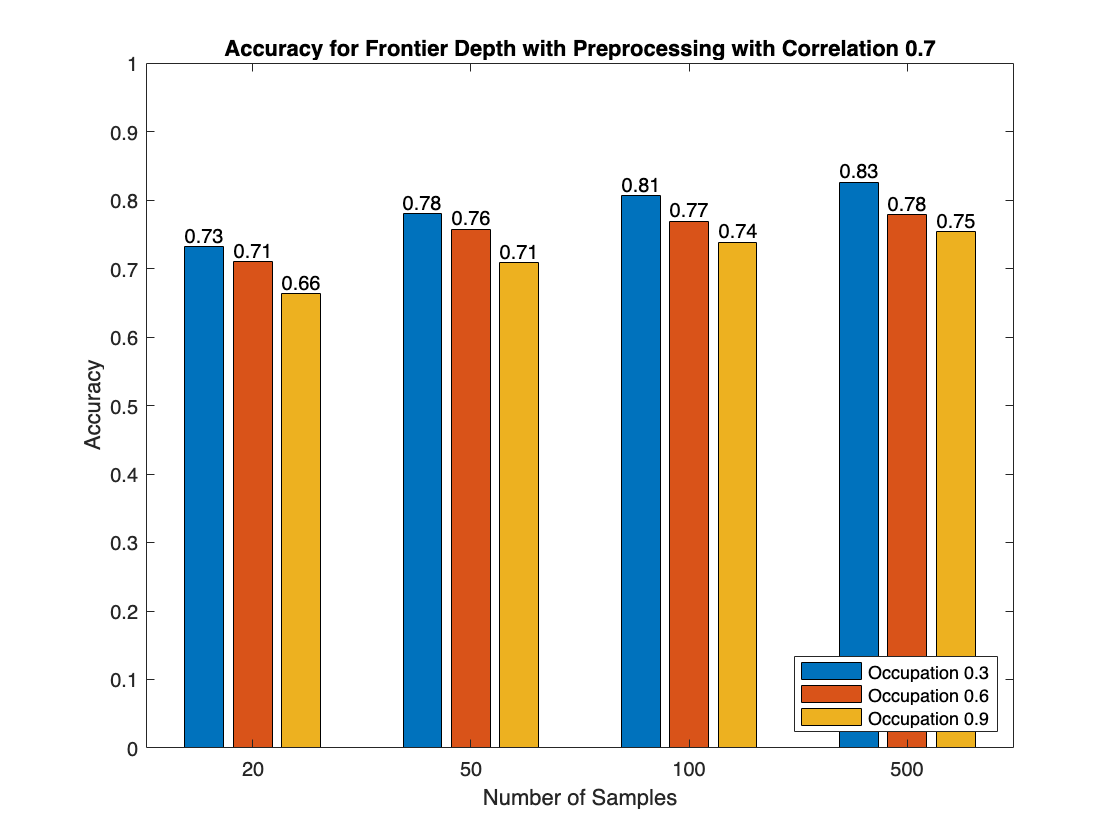

a = NaN(3,4);
a(:,:)= matrixPFinal(:,:,1,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"},'Location','southeast')
title("Accuracy for Frontier Depth with Preprocessing with Correlation 0.7")

#### Accuracy for Frontier Depth with Preprocessing with Correlation 0.8

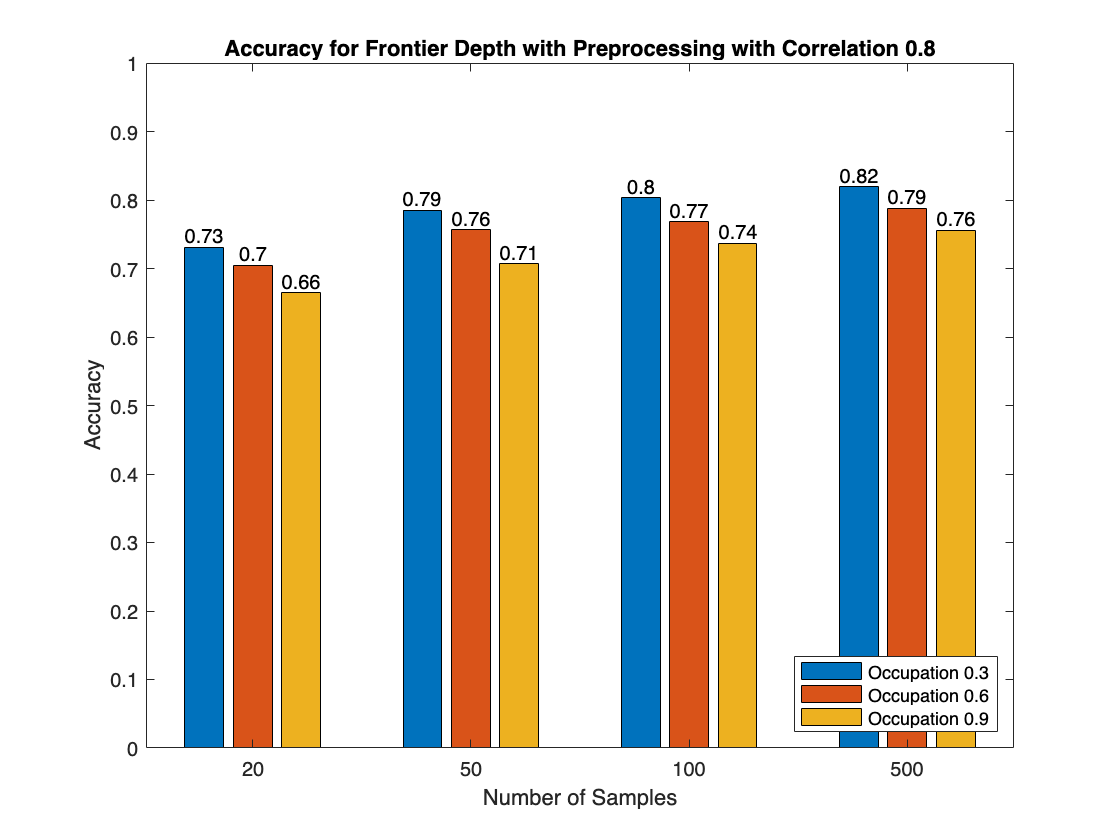

a = NaN(3,4);
a(:,:)= matrixPFinal(:,:,2,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"},'Location','southeast')
title("Accuracy for Frontier Depth with Preprocessing with Correlation 0.8")

#### Accuracy for Frontier Depth with Preprocessing with Correlation 0.7

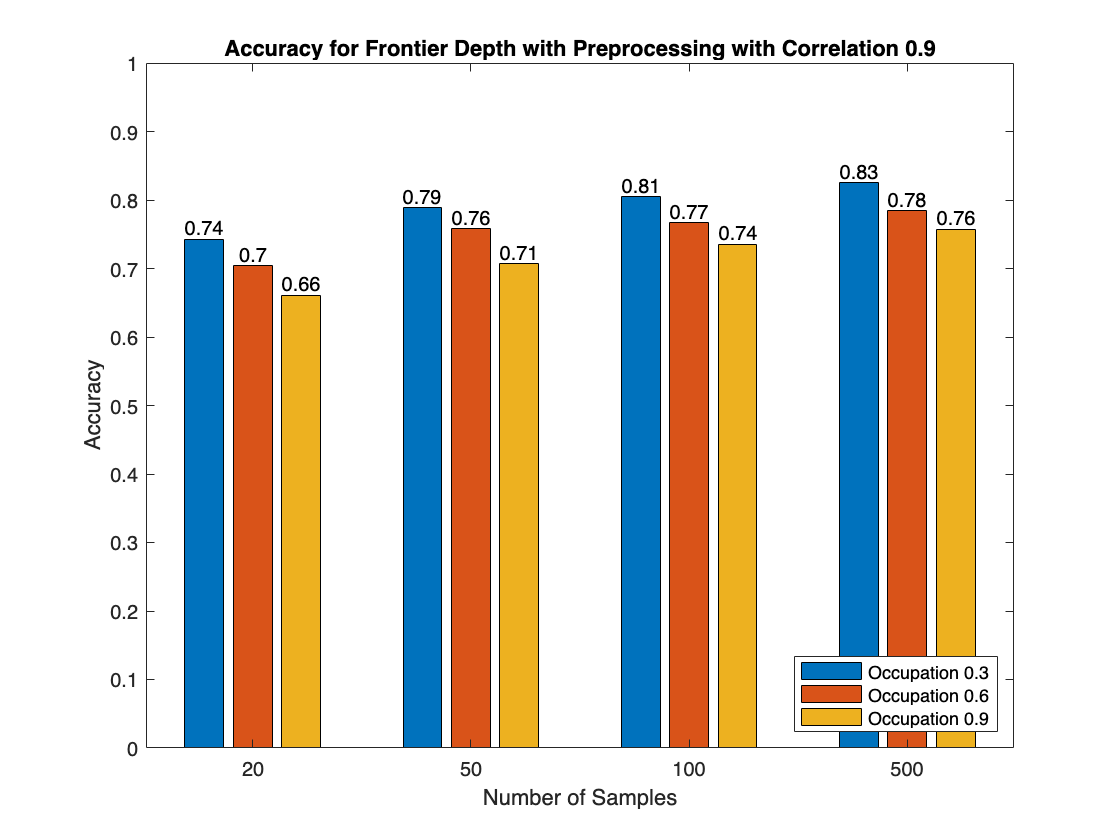

a = NaN(3,4);
a(:,:)= matrixPFinal(:,:,3,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"},'Location','southeast')
title("Accuracy for Frontier Depth with Preprocessing with Correlation 0.9")

# Analyzing Results

## Frontier Depth with Preprocessing

matrixNPFinal= NaN(length(nicheOccupations),length(samples),2);
valFinalMin = 1;
valFinalMax = 0;
for i=1:3
    for j=1:4
            matrixNPFinal(i,j,1)=mean(matrixNoPreprocessingFinal(:,i,j,1));
            matrixNPFinal(i,j,2)=mean(matrixNoPreprocessingFinal(:,i,j,2));
    end
    [valMin,idxMin]=min(matrixNPFinal(i,:,2));
    if valFinalMin > valMin
        iFinalMin = i; jFinalMin = idxMin; valFinalMin = valMin;
    end
    [valMax,idxMax]=max(matrixNPFinal(i,:,2));
    if valFinalMax < valMax
        iFinalMax = i; jFinalMax = idxMax; valFinalMax = valMax;
    end

end

i: occupation, j: number of samples

The experimental conditions that lead to the **worst **results are:

valFinalMin, iFinalMin, jFinalMin

valFinalMin = 0.6690

iFinalMin = 3

jFinalMin = 1

The experimental conditions that lead to the **best **results are:

valFinalMax, iFinalMax, jFinalMax

valFinalMax = 0.8336

iFinalMax = 1

jFinalMax = 4

### Visualizing Results

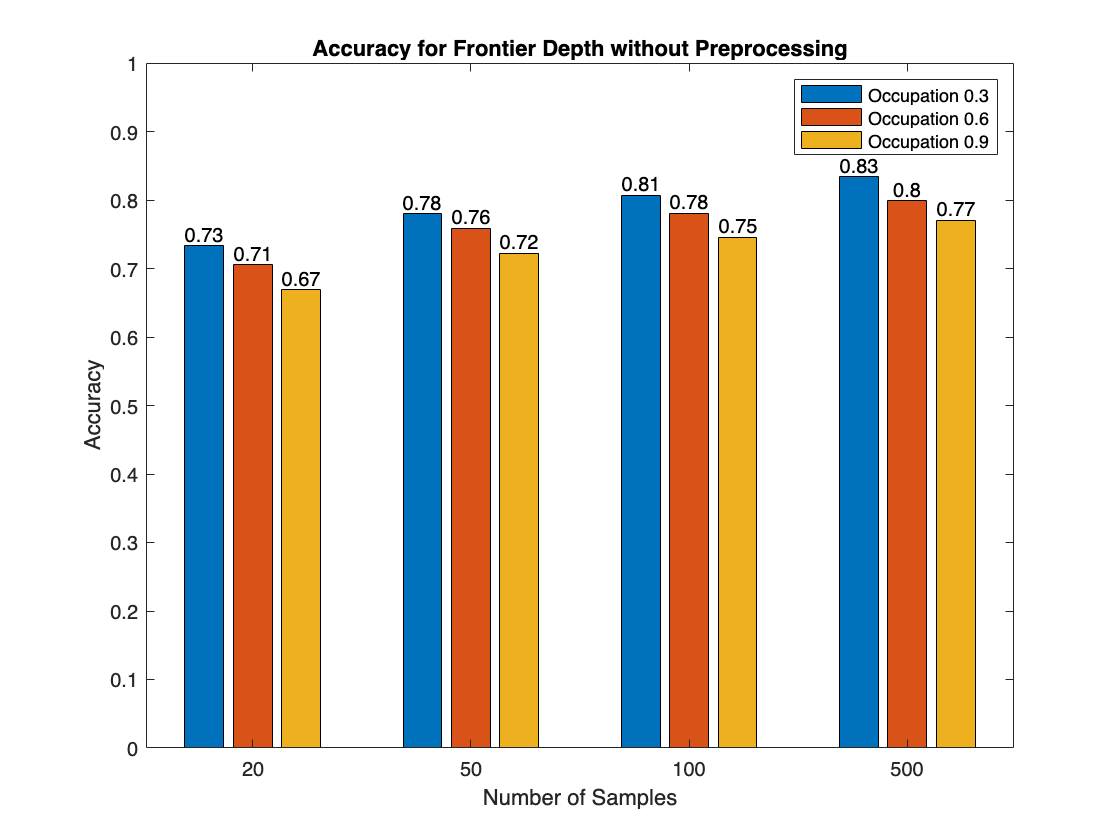

a = NaN(3,4);
a(:,:)= matrixNPFinal(:,:,2);
b = bar(a');
xlabel("Number of Samples")
xticklabels({"20","50","100","500"})
ylim([0 1])
ylabel("Accuracy")

xtips1 = b(1).XEndPoints;
ytips1 = b(1).YEndPoints;
labels1 = string(round(b(1).YData,2));
text(xtips1,ytips1,labels1,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips2 = b(2).XEndPoints;
ytips2 = b(2).YEndPoints;
labels2 = string(round(b(2).YData, 2));
text(xtips2,ytips2,labels2,'HorizontalAlignment','center','VerticalAlignment','bottom')

xtips3 = b(3).XEndPoints;
ytips3 = b(3).YEndPoints;
labels3 = string(round(b(3).YData,2));
text(xtips3,ytips3,labels3,'HorizontalAlignment','center','VerticalAlignment','bottom')

legend({"Occupation 0.3","Occupation 0.6","Occupation 0.9"})
title("Accuracy for Frontier Depth without Preprocessing")

## Visualizing Results Using a Boxplot

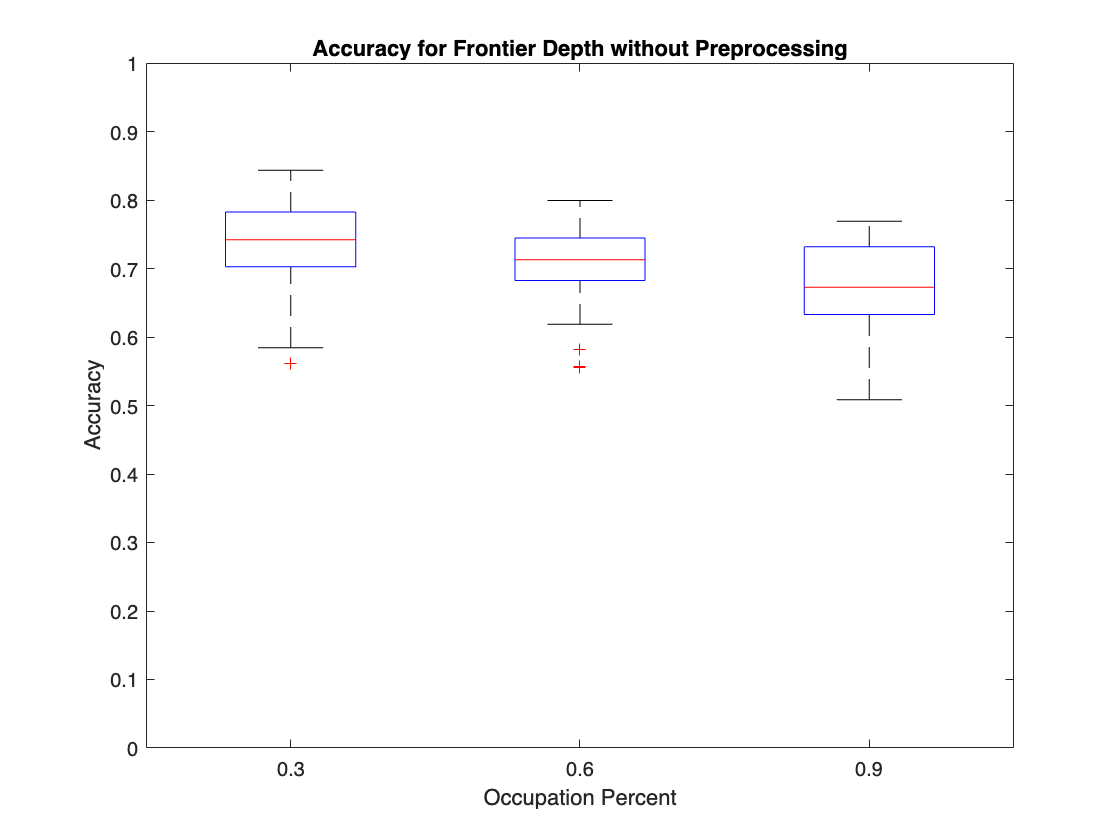

boxplot(matrixNoPreprocessingFinal(:,:,1,2))
xlabel("Number of Samples")
xticklabels({"0.3","0.6","0.9"})
ylim([0 1])
ylabel("Accuracy")
xlabel({"Occupation Percent"})
title("Accuracy for Frontier Depth without Preprocessing")

# Experimental Design Matrix for Frontier Methods with Preprocessing

## *Chocó Map*

### 0. Preparing environment

#### 1. Clear command window, workspace variables, and close all figures. Turn off warnings.

clear; clc; close all;
warning('off', 'all');

#### 2. Set the path to the folder containing the layer data

layerfolder = 'data/layers/';

#### 3. Read in the layer data from the specified folder using ReadLayers:

-  To execute ReadLayers, there is one required input and three optional inputs.

                Layers = ReadLayers(layer_folder, parallel, nanvalue)

Layers = ReadLayers(layerfolder);

----Reading layers----
Elapsed time is 2.416712 seconds.


warning("off", "all")
mapsAmount = 5;
[bestMap, averageMap, medianMap, worstMap, metricAlllMaps] = results(Layers,mapsAmount)

map = 1

map = 2

map = 3

map = 4

map = 5

bestMap = 5×2 cell array
    {[     0.8769]}    {[     0.7683]}
    {  1×1  struct}    {  1×1  struct}
    {499×22 table }    {498×22 table }
    {  1×1  struct}    {  1×1  struct}
    {  1×1  struct}    {  1×1  struct}


averageMap = 5×1 cell array
    {[    0.7903]}
    { 1×1  struct}
    {50×22 table }
    { 1×1  struct}
    { 1×1  struct}


medianMap = 5×1 cell array
    {[    0.7903]}
    { 1×1  struct}
    {50×22 table }
    { 1×1  struct}
    { 1×1  struct}


worstMap = 5×2 cell array
    {[    0.7123]}    {[    0.4948]}
    { 1×1  struct}    { 1×1  struct}
    {20×22 table }    {20×22 table }
    { 1×1  struct}    { 1×1  struct}
    { 1×1  struct}    { 1×1  struct}


metricAlllMaps =     0.7903
    0.8326
    0.7598
    0.8171
    0.7358
